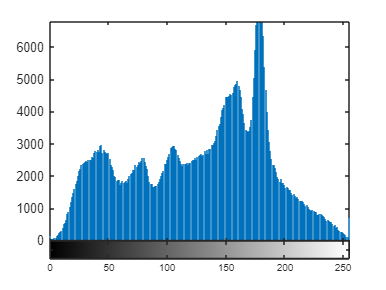

%%%%%%%%%%%%%%%%%%%%
%-----Settings-----%

eyeWidth = 260;   %Distans (px) från sidan till närmsta öga horisontell längd
eyeHeight = 150;  %Distans (px) från topp av bild till närmsta öga

debug = true;
%------------------%4

Files = dir("DB1\db1_01.jpg"); %Läs från mapp

%Skapa bilder på ansiktet
face = imread(Files.folder + "\" + Files.name); % Vanlig
face_eq = histeq(face);                         % Histogramkompenserad
facebw = imbinarize(rgb2gray(face_eq),0.7);       % Trösklad 85%

if debug == true
    imhist(face);
end

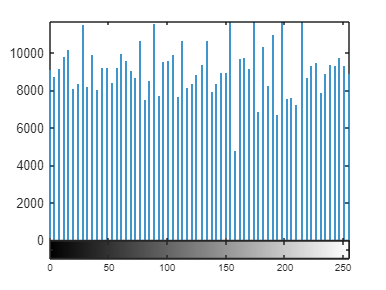


imhist(face_eq)

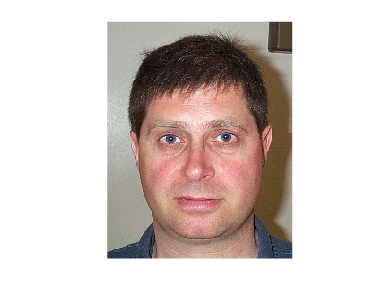


imshow(face);

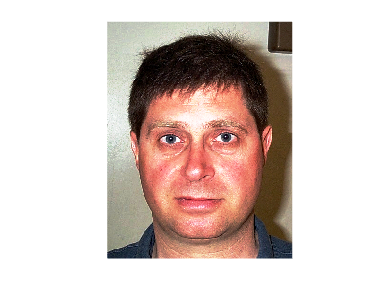

imshow(face_eq);

facebw = uint8(facebw);

meanr = mean(mean(face_eq(:,:,1).*facebw));
meang = mean(mean(face_eq(:,:,2).*facebw));
meanb = mean(mean(face_eq(:,:,3).*facebw));
meanmean = (meanr+meang+meanb)/3;

%Vi vill att alla färgkanaler ska ha samma mean av typ 170
multr = meanmean/meanr;
multg = meanmean/meang;
multb = meanmean/meanb;

face(:,:,1) = face_eq(:,:,1)*multr;
face(:,:,2) = face_eq(:,:,2)*multg;
face(:,:,3) = face_eq(:,:,3)*multb;

face_BW = rgb2gray(face);
face_BW_eq = histeq(face_BW); 

max(max(face_BW))

ans = uint8
247

min(min(face_BW))

ans = uint8
0

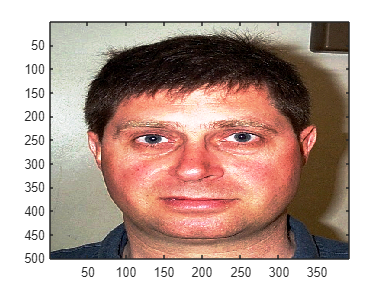


eye1X = eyeWidth;
eye2X = size(face,2) - eyeWidth;
eyeY = eyeHeight;

HSVface = rgb2hsv(face_eq);

%----- EYE MAP------ %
YCbCrFace = rgb2ycbcr(face_eq);

image(ycbcr2rgb(YCbCrFace))

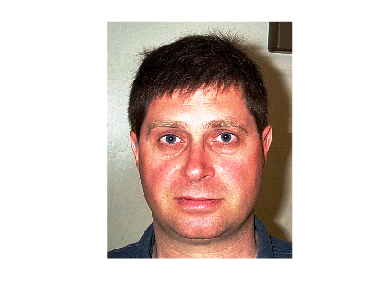


Y = double(YCbCrFace(:,:,1));
Cb = normalize(double(YCbCrFace(:,:,2)), "norm",1);
Cr = normalize(double(YCbCrFace(:,:,3)),"norm",1);
Cr_ = 1-Cr;
% This is weird. should it be purple?
imshow(ycbcr2rgb(YCbCrFace));

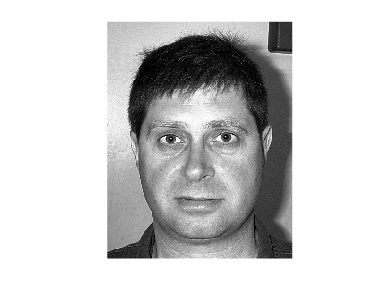


imshowpair(Y, (face_eq)); % Y 

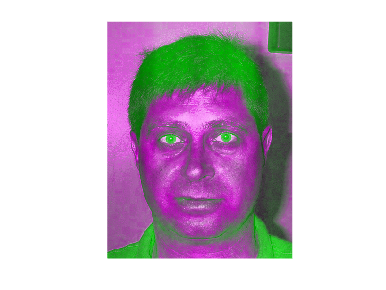

imshowpair(Cb, (face_eq)); % Cb 

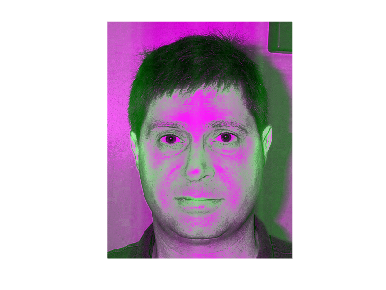

imshowpair(Cr, (face_eq)); % Cr 

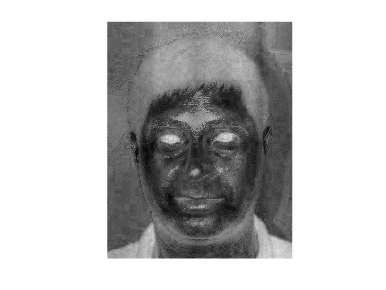

imshow(Cb, [])

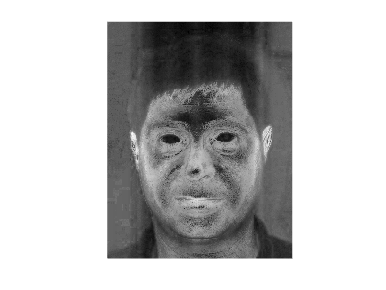

imshow(Cr, [])

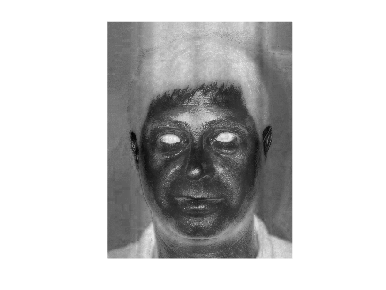


eyeMapC = (Cb.^2 + Cr_.^2 + (Cb./Cr))/3;

imshow(eyeMapC, []);

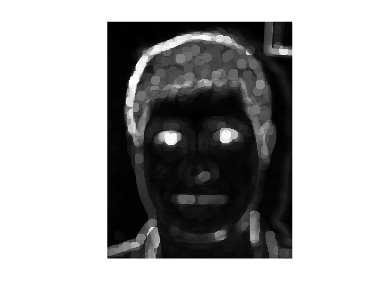


radius = 10;  
se = strel('disk', radius);
% Dilation 
dilated_image = imdilate(Y, se);

% Erosion
eroded_image = imerode(Y, se);
eyemapL = dilated_image./(eroded_image+1);

imshow(eyemapL, []);

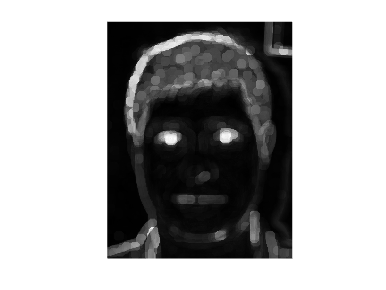


andimg= eyemapL.*eyeMapC;
imshow(andimg, []);

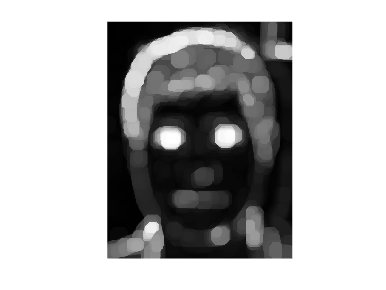


newimg= imdilate(andimg, se);
imshow(newimg, []);


size(face)

ans =    500   392     3




%----- HISTOGRAM Enchancments------- %

figure
subplot(1, 2, 1);
imshow(face_BW);
title('Original grayscale image');

subplot(1, 2, 2);
imshow(face_BW_eq);
title('Histogram Equalized Image');

histogram = imhist(face_BW_eq);
histMean = mean(histogram)

histMean = 765.6250

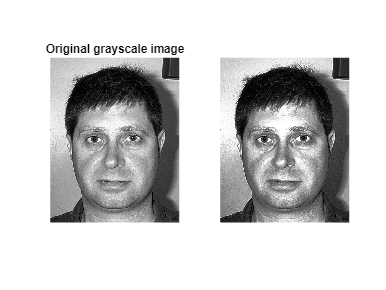

Dark image



brightnessThreshold = 0.5;
contrastThreshold = 0.5;

if (histogram(1) > brightnessThreshold * histMean)
    disp("Dark image")

    enhancedImage = histeq(face_BW_eq);
    imshowpair(face_BW_eq, enhancedImage);

elseif (histogram(end) > contrastThreshold * histMean)
     disp("bright image")

     enhancedImg = imadjust(face_BW_eq);
     imshowpair(face_BW_eq, enhancedImg)
else
     disp("poor contrast")
     enchancedImg = face_BW_eq;
end

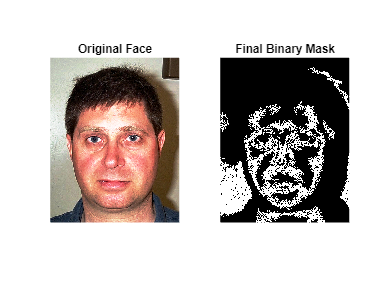



%----- Human faces determination----- %

% Skin Region Segmentation
% Steps for face mask in report on lisam
stats = regionprops(face_BW, 'Area', 'BoundingBox');

% Step 1
for i = 1:length(stats)
    numHoles = bweuler(face_BW == i);

    % If there are no holes, discard the region
    if numHoles == 0
        face_BW(face_BW == i) = 0;
    end
end

% Step 2
for i = 1:length(stats)
    width = stats(i).BoundingBox(3);
    height = stats(i).BoundingBox(4);

    % Compute the ratio of width to height
    ratio = width / height;

    % Discard the region if the ratio is outside the desired range [0.8, 2.0]
    if ratio < 0.8 || ratio > 2.0
        face_BW(face_BW == i) = 0;
    end
end

% Step 3
for i = 1:length(stats)
    areaRatio = stats(i).Area / (stats(i).BoundingBox(3) * stats(i).BoundingBox(4));

    % Discard the region if the ratio is less than 0
    if areaRatio < 0
        face_BW(face_BW == i) = 0;
    end
end

% Step 4
face_BW = bwareaopen(face_BW, 400);

% Step 5
for i = 1:length(stats)
    width = stats(i).BoundingBox(3);
    height = stats(i).BoundingBox(4);

    % Discard the region if width or height is less than 20
    if width < 20 || height < 20
        face_BW(face_BW == i) = 0;
    end
end

% Display the final result
figure;
subplot(1, 2, 1);
imshow(face_eq);
title('Original Face');

subplot(1, 2, 2);
imshow(face_BW);
title('Final Binary Mask');